# Interpolate Australian Temperatures

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

data = readtable("./data/marchTemps.csv")

data = 139×3 table
    latitude    longitude    temperature
    ________    _________    ___________

      -11.4      130.42        27.347   
    -13.833      131.18        27.886   
     -14.45      132.27        30.193   
     -11.15      132.13        28.561   
     -11.65      133.38        28.393   
    -13.333      133.08        27.482   
    -13.667      134.33        27.866   
    -13.983      136.47        27.346   
    -13.767      143.12        26.289   
    -12.783       143.3        26.415   
    -14.967      145.32        26.735   
     -16.45         123         32.21   
    -18.683      121.78        33.891   
    -17.583      123.82        29.692   
    -15.517      123.15        29.393   
    -16.417       126.1        30.566   


lonvec = 110:155;
latvec = -45:-10;
[longrid, latgrid] = meshgrid(lonvec, latvec);
Tgrid = griddata(data.longitude, data.latitude, data.temperature, longrid, latgrid);

## Task 1

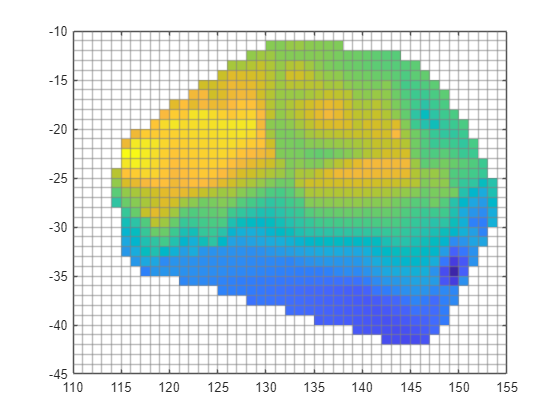

im = pcolor(longrid, latgrid, Tgrid);
im.EdgeColor = 0.5*[1 1 1];
im.EdgeAlpha = 0.5;

## Task 2

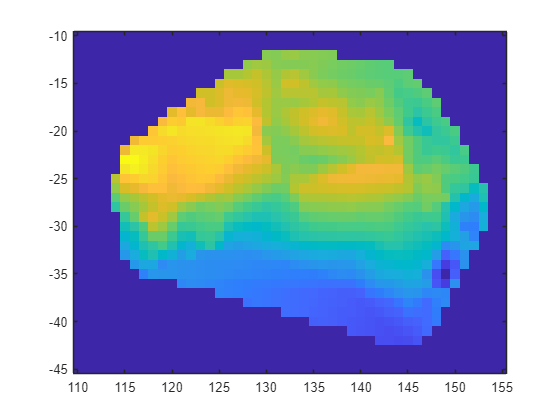

im2 = imagesc(lonvec, latvec, Tgrid);
axis xy